# FEM 2D - Poisson's equation

Solve eq.: $\frac{\partial ^2 u}{\partial x^2} + \frac{\partial ^2 u}{\partial y^2} = 4$ on a circular domain $\Omega$: $x^2 + y^2 \le 1$, with boundary condition: $u\left(\{x,y\} \in \delta \Omega\right) = 0 \,\mathrm{V}$. 

## Constants

Define right hand side value $f = 4$ and B.C. value:

f = 4;
b = 0;

% Conductivity of inner element
sigma_in = 2;
% Conductivity of background
sigma_bkg = 1;

## Mesh

Load mesh from file *meshCircle.mat*:

load('meshCircle.mat')

Find number of elements $N_{\mathrm{e}}$ (triangles) and global nodes $N_{\mathrm{n}}$:

nElems = size(t, 1);
nNodes = size(p, 1);

 Complete the function  that creates the coupling matrix $\underset{3N_{\mathrm{e}} \times N_{\mathrm{n}}}{\bf{\it{C}}}$:

C = getCouplMatrix(p, t);

Find global node numbers that are on the boundary of the comp. domain $\Omega$:

temp = 1:nElems;
isBoundary = abs(sqrt(sum(p.^2, 2)) - 1) <= 1e-5;
boundaryNums = temp(isBoundary);
inNums = temp(~isBoundary);

Add triagular elements with conductivity

% Create conductivity array for nodes
sigma = ones(nNodes, 1) * sigma_bkg; % Background conductivity

% Compute centroids of each triangle
centroids = (p(t(:,1),:) + p(t(:,2),:) + p(t(:,3),:)) / 3;

% Compute distance from the origin
r = sqrt(sum(centroids .^ 2, 2)); 
% Compute the angle from the origin
theta = atan2(centroids(:,2), centroids(:,1));

% Select elements in the top-right region (angle between 0 and pi/2)
% and distance in the range [0.3, 0.5]
isSelected = (r > 0.3) & (r < 0.5) & (theta > 0) & (theta < pi/2);

% Assign higher conductivity to the nodes of selected elements
for i = find(isSelected)'
    nodes = t(i, :);
    sigma(nodes) = sigma_in;
end


Arbitary material for forwarde problem

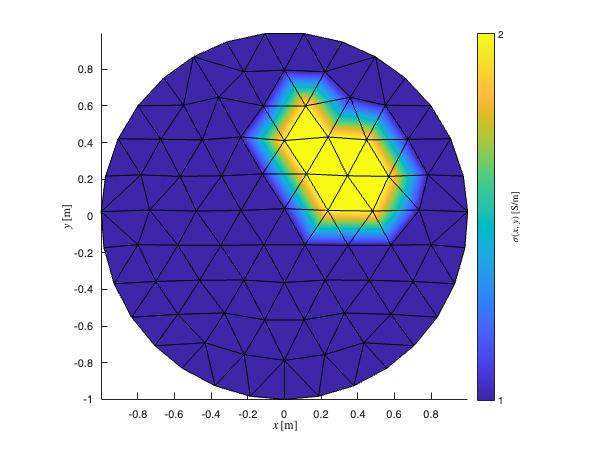

% Plot the mesh with conductivity colouring
figure
trisurf(t, p(:,1), p(:,2), zeros(nNodes,1), sigma, 'EdgeColor', 'k', 'FaceColor', 'interp');
axis equal
view(2)
hold on
grid off
xlabel('$x\,\mathrm{[m]}$', 'Interpreter', 'latex')
ylabel('$y\,\mathrm{[m]}$', 'Interpreter', 'latex')

% Colour bar for conductivity
cb = colorbar;
cb.Label.String = '$\sigma(x, y)\,\mathrm{[S/m]}$';
cb.Label.Interpreter = 'latex';
cb.Limits = [min(sigma), max(sigma)];
cb.Ticks = unique(sigma); % Show only existing conductivity values

## Exact Solution

Find the exact solution $u(x, y) = 1-x^2-y^2$ for the global points and plot it on the triangles:

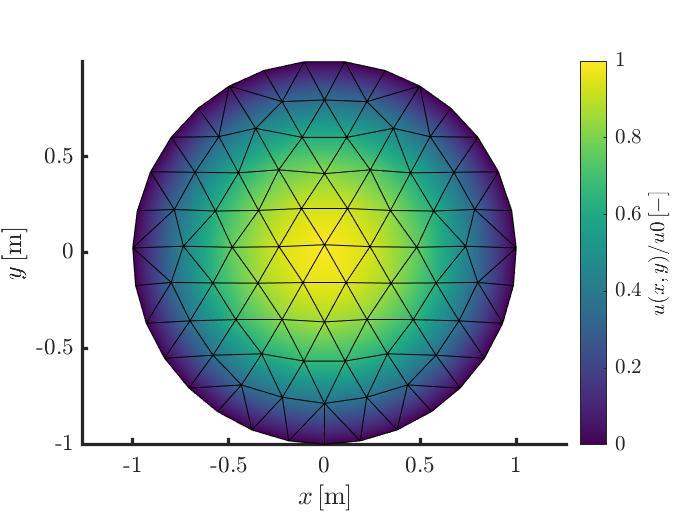

## Weak Formulation


$$   \[
   \int_\Omega \sigma \nabla \phi \cdot \nabla v \, d\Omega = 0
   \]$$


## Stiffness Matrix

For each triangular element, we form a local stiffness matrix �$\[
   K_e

   \]$ which represents the relationships between the voltage values at the nodes of the element.


$$\[
   K_e = \int_e \sigma \nabla \phi_e \cdot \nabla \phi_e \, dA
   \]$$


% Assemble the global stiffness matrix (K) and load vector (F)
K = sparse(nNodes, nNodes);  % Global stiffness matrix
F = zeros(nNodes, 1);        % Global load vector

% Loop over each element and calculate the local stiffness matrix
for e = 1:nElems
    nodes = t(e, :);  % Get nodes of the element
    coords = p(nodes, :);  % Get coordinates of the element nodes

    % Compute local element stiffness matrix
    Ke = computeElementStiffness(coords, sigma(nodes));
    
    % Assemble the local stiffness matrix into the global stiffness matrix
    K(nodes, nodes) = K(nodes, nodes) + Ke;
end

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.

Error in fem2DSolution>computeElementStiffness (line 93)
    Ke = A * (B' * B) * sigma;

Related documentation


% Apply boundary conditions (Dirichlet for fixed voltages)
% For simplicity, assuming boundary voltage values are set in 'boundaryVoltages'
% Setting Dirichlet boundary condition for boundary nodes
K(boundaryNodes, :) = 0;
K(boundaryNodes, boundaryNodes) = eye(length(boundaryNodes));  % Identity matrix for Dirichlet
F(boundaryNodes) = boundaryVoltages;  % Voltage values at boundary nodes

% Solve the system of equations K*phi = F for the potentials at all nodes
phi = K \ F;

% Calculate boundary voltages (only for boundary nodes)
boundaryVoltagesCalculated = phi(boundaryNodes);

% Function to compute the local stiffness matrix for each triangular element
function Ke = computeElementStiffness(coords, sigma)
    % Calculate the area of the triangle using determinant
    A = abs(det([1, coords(1,:); 1, coords(2,:); 1, coords(3,:)])) / 2;

    % Compute the gradient of the shape functions (B-matrix)
    B = computeGradientShapeFunctions(coords);

    % Element stiffness matrix for the triangular element
    % B' * B is a 3x3 matrix, and A is a scalar.
    % We need to use A * (B' * B) for assembling the stiffness matrix.
    Ke = A * (B' * B) * sigma;
end


% Function to compute the gradient of the shape functions for a triangle
function B = computeGradientShapeFunctions(coords)
    % Calculate the Jacobian matrix for the transformation from reference
    % element to real element (affine transformation)
    J = [coords(2,1) - coords(1,1), coords(3,1) - coords(1,1); 
         coords(2,2) - coords(1,2), coords(3,2) - coords(1,2)];

    % Inverse of the Jacobian matrix
    J_inv = inv(J);
    
    % The gradient of the shape functions (B-matrix), which is 2x3 for 2D triangles
    B = J_inv;
end


## Matrix assembly

Initialize zero matrices $\underset{3N_{\mathrm{e}} \times 3N_{\mathrm{e}}}{\bf{\it{K}}}, \underset{3N_{\mathrm{e}} \times 1}{\bf{\it{g}}}$ and vector for areas of individual triangles:

K = zeros(nElems*3);
g = zeros(nElems*3, 1);
area = zeros(nElems, 1);

Loop over all elements:

for iE = 1:nElems

Find indeces to put 3 x 3 matrix on the diagonal

    ind = (iE-1)*3+1:iE*3;

Find $x$ and $y
$ nodes of curr. triangle:

    x = p(t(iE, :), 1);
    y = p(t(iE, :), 2);

Compute $a$, $b
$, $c$ coefficients of curr. triangle:

$         a_1 = x_2 y_3 - y_2 x_3 \\ 
         a_2 = x_3 y_1 - y_3 x_1 \\ 
         a_3 = x_1 y_2 - y_1 x_2 $ ,    $b_1 = y_2 - y_3 \\ 
b_2 = y_3 - y_1 \\ 
b_3 = y_1 - y_2$,    $c_1 = x_3 - x_2 \\ 
c_2 = x_1 - x_3 \\ 
c_3 = x_2 - x_1$.

    a1 = x(2)*y(3) - y(2)*x(3);
    a2 = x(3)*y(1) - y(3)*x(1);
    a3 = x(1)*y(2) - y(1)*x(2);
    b1 = y(2) - y(3);
    b2 = y(3) - y(1);
    b3 = y(1) - y(2);
    c1 = x(3) - x(2);
    c2 = x(1) - x(3);
    c3 = x(2) - x(1);

 Compute area $A = \frac{1}{2}\left(b_1c_2 - c_1b_2\right)$

    area(iE) = 1/2*(b1*c2 - c1*b2);

Compute $\bf{\it{K}}^{(e)}$ of the $e$-th element $K_{i,j}  = \frac{b_i b_j + c_i c_j}{4 \Delta_e}$:

    K(ind, ind) = [b1^2 + c1^2, b1*b2 + c1*c2, b1*b3 + c1*c3; ...
        b2*b1 + c2*c1, b2^2 + c2^2, b2*b3 + c2*c3; ...
        b3*b1 + c3*c1, b3*b2 + c3*c2, b3^2 + c3^2]/(4*area(iE));

Compute $\bf{\it{g}}^{(e)}$ of the $e$-th element $g_{j}  = \frac{f \Delta_e}{3}$:

    g(ind, 1) = 1/3*f*area(iE);    
end

Apply coupling of $\bf{\it{K}}$and $\bf{\it{g}}$: $\bf{\it{K}}_{\mathrm{c}} = \bf{\it{C}}^{\mathrm{T}} \bf{\it{K}}\bf{\it{C}},

\bf{\it{g}}_{\mathrm{c}} = \bf{\it{C}}^{\mathrm{T}} \bf{\it{g}}$

Kc = C'*K*C;
gc = C'*g;

## Boundary conditions

Apply boundary conditions. As $u = 0$ on the boundary, basically remove all entries corresponding to boundary nodes from the system. 

Kc(boundaryNums, :) = [];
Kc(:, boundaryNums) = [];
gc(boundaryNums, :) = [];

## Solution

Solve the reduced linear system and plug the results on proper positions corresponding to the inside nodes.

temp = Kc\gc;
u = zeros(nNodes, 1);
u(inNums, 1) = temp;

## Visualization of Results

Plot the FEM solution 

figure
trisurf(t,p(:,1),p(:,2),0*p(:,1),u,'edgecolor','k','facecolor','interp');
view(2)
axis equal
hold on
title('FEM')
xlabel('$x\,\mathrm{[m]}$', 'Interpreter', 'latex')
ylabel('$y\,\mathrm{[m]}$', 'Interpreter', 'latex')
cb = colorbar;
cb.Label.String = '$u(x, y)/u0\,\mathrm{[-]}$';
cb.Label.Interpreter = 'latex';

Plot the absolute error between the solution found by FEM and exact solution. 

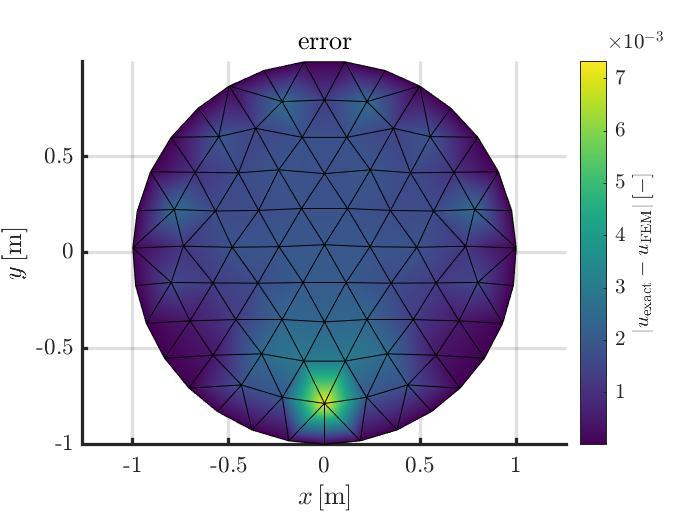

figure
trisurf(t,p(:,1),p(:,2),0*p(:,1),abs(uEx - u),'edgecolor','k','facecolor','interp');
view(2)
axis equal
hold on
title('error')
xlabel('$x\,\mathrm{[m]}$', 'Interpreter', 'latex')
ylabel('$y\,\mathrm{[m]}$', 'Interpreter', 'latex')
cb = colorbar;
cb.Label.String = '$|u_{\mathrm{exact}} - u_{\mathrm{FEM}}|\,\mathrm{[-]}$';
cb.Label.Interpreter = 'latex';